### Part1

syms theta1
syms theta2
syms theta3
syms theta4
a1 = [0;0;505]

a1 =      0
     0
   505


a2 = [500*cos(theta2);500*sin(theta2);0]

$$a2 = \left(\begin{array}{c} 500\,\cos\left(\theta_{2}\right)\\ 500\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$

a3 = [566.23*cos(theta3);566.23*sin(theta3);0]

$$a3 = \left(\begin{array}{c} \frac{56623\,\cos\left(\theta_{3}\right)}{100}\\ \frac{56623\,\sin\left(\theta_{3}\right)}{100}\\ 0 \end{array}\right)$$

a4 = [195.54*cos(theta4);195.54*sin(theta4);0]

$$a4 = \left(\begin{array}{c} \frac{9777\,\cos\left(\theta_{4}\right)}{50}\\ \frac{9777\,\sin\left(\theta_{4}\right)}{50}\\ 0 \end{array}\right)$$




Q1 = [cos(theta1),0,sin(theta1);sin(theta1),0,-cos(theta1);0,1,0]

$$Q1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

Q2 = [cos(theta2),-sin(theta2),0;sin(theta2),cos(theta2),0;0,0,1]

$$Q2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Q3 = [cos(theta3),-sin(theta3),0;sin(theta3),cos(theta3),0;0,0,1]

$$Q3 = \left(\begin{array}{ccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Q4 = [cos(theta4),-sin(theta4),0;sin(theta4),cos(theta4),0;0,0,1]

$$Q4 = \left(\begin{array}{ccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$




Q = simplify(Q1*Q2*Q3*Q4)

$$Q = \left(\begin{array}{ccc} \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) & \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) & 0 \end{array}\right)$$

P = simplify(a1+Q1*a2+Q1*Q2*a3+Q1*Q2*Q3*a4)

$$P = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{100}\\ \frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{100}\\ \frac{9777\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{50}+\frac{56623\,\sin\left(\theta_{2}+\theta_{3}\right)}{100}+500\,\sin\left(\theta_{2}\right)+505 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=19554\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)+56623\,\cos\left(\theta_{2}+\theta_{3}\right)+50000\,\cos\left(\theta_{2}\right) \end{array}$$

start_point = [743.25;0;1148.65];
Q_start = [1,0,0;0,0,-1;0,1,0];
Q_end = [1,0,0;0,0,-1;0,1,0];
phi = acos((trace(Q_end)-1)/2);
end_point = [700;50;600];

[theta1_start ,theta2_start, theta3_start, theta4_start] = IKP(start_point,Q_start,P,Q,theta1,theta2,theta3,theta4);
[theta1_end ,theta2_end, theta3_end, theta4_end] = IKP(end_point,Q_end,P,Q,theta1,theta2,theta3,theta4);
theta_I = [theta1_start ,theta2_start, theta3_start, theta4_start]'

$$theta\_I = \left(\begin{array}{c} 0\\ 0.16072222740936671901282159584478\\ 1.3142880796881244774440062679067\\ -1.4750103070974911964562503695497 \end{array}\right)$$

theta_F = [theta1_end ,theta2_end, theta3_end, theta4_end]'

$$theta\_F = \left(\begin{array}{c} -163.29151052188395807362508494068\\ 13.956869950771055967419982482091\\ 66.98175763639492739138001307563\\ 0.67147394138335051479729695818477 \end{array}\right)$$

% [P,Q] = FKP(theta1_sol ,theta2_sol, theta3_sol, theta4_sol)

T = 1.5;
theta_I = [theta1_start, theta2_start, theta3_start, theta4_start];
theta_F = [theta1_end, theta2_end, theta3_end, theta4_end];

time_steps = 0:0.1:T;
num_steps = numel(time_steps);

theta_plots = zeros(num_steps, 4);

for t_idx = 1:num_steps
    t = time_steps(t_idx);
    tau = t / T;
    s = 6 * tau.^5 - 15 * tau.^4 + 10 * tau.^3;
    joint_theta = theta_I' + (theta_F' - theta_I') * s
    theta_plots(t_idx, :) = joint_theta';
end

$$joint\_theta = \left(\begin{array}{c} 0\\ 0.16072222740936671901282159584478\\ 1.3142880796881244774440062679067\\ -1.4750103070974911964562503695497 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -0.43673423258593754992311457528487\\ 0.1976209612709602552103613861568\\ 1.4899201859197906766022561562203\\ -1.4692693892259987327560175275506 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -3.1377774110753322645952832995838\\ 0.42582627689650251627167998426443\\ 2.5761412033377910537863432663724\\ -1.4337638897755719357495891537988 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -9.4578442894275188516243649197642\\ 0.95979510354647576028056435437613\\ 5.11774791641258250221917978221\\ -1.3506859394254808445404449083273 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -19.900114633398819646943880465952\\ 1.8420400149462018011841427813451\\ 9.3170934165189053557921241266736\\ -1.2134211867137400711616580758782 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -34.271057763852188731501561036933\\ 3.0562100212013261909007442509828\\ 15.096349591589552249504649671997\\ -1.0245136129718824422425429057042 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -51.83525710006684365089154696357\\ 4.5401713607133013540271907475746\\ 22.15976961576913199444385226895\\ -0.79363034725973280363592430583367 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -71.470234703047943146053200062422\\ 6.1990882920948736099219235728249\\ 30.055950439067851956054829604876\\ -0.53552648130018122022505021958645 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -91.821275818836033056571355599917\\ 7.9185038860855506081909658657186\\ 38.240095277015207203322856811402\\ -0.26800988441395922312627972591287 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -111.45625342181711442273353797711\\ 9.5774208174671213324056133303607\\ 46.136276100313919874380167074586\\ -0.0099060184544078780230291055312623 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -129.02045275803176934212352390375\\ 11.061382156979096495532059826953\\ 53.19969612449349961931936967154\\ 0.22097724725774176058358949433926 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -143.39139588848515202343080751597\\ 12.275552163234222034008725317046\\ 58.978952299564151980947145521419\\ 0.40988482099959956823342226391251 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -153.83366623245643922200072002092\\ 13.157797074633946926152239723559\\ 63.178297799670469366604839561327\\ 0.54714957371134016288149149696239 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -160.1537331108085187346266776913\\ 13.691765901283911123675619932579\\ 65.719904512745217755205079928785\\ 0.63022752406142984658623464716503 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -162.85477628929791500725973843074\\ 13.919971216909453516365695866364\\ 66.806125530163218758921122803001\\ 0.66573302351185666407222441251473 \end{array}\right)$$

$$joint\_theta = \left(\begin{array}{c} -163.29151052188395807362508494068\\ 13.956869950771055967419982482091\\ 66.98175763639492739138001307563\\ 0.67147394138335051479729695818477 \end{array}\right)$$

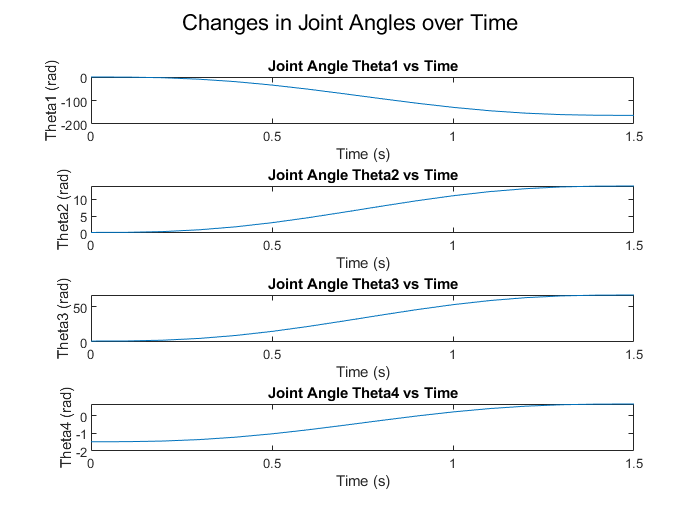


% Create four separate plots for each joint angle
figure;

for i = 1:4
    subplot(4, 1, i);
    plot(time_steps, theta_plots(:, i));
    xlabel('Time (s)');
    ylabel(['Theta', num2str(i), ' (rad)']);
    title(['Joint Angle Theta', num2str(i), ' vs Time']);
end

sgtitle('Changes in Joint Angles over Time');

### Part2

x = 700;
y = [50, 60, 80, 100, 120, 140, 150]

y =     50    60    80   100   120   140   150


z = 600;
init_guess = [0,1,2,3];
theta_mid_list = []; 
for i = 1:numel(y)
    point = [x; y(i); z];
    [theta1_sol ,theta2_sol, theta3_sol, theta4_sol] = IKP_mid(point,Q_end,P,Q,theta1,theta2,theta3,theta4,init_guess);
    theta_mid = [theta1_sol, theta2_sol, theta3_sol, theta4_sol]';
    theta_mid_list = [theta_mid_list theta_mid];
    init_guess = theta_mid';
end


disp('List of theta_mid values:');

List of theta_mid values:


disp(theta_mid_list);

$$\left(\begin{array}{ccccccc} -6.2118778423942961504929157767059 & -6.1976800135013818334007744997811 & -6.1693933000358784107014491838438 & -6.1412882525754225541124351494565 & -6.1134070332112480268708475149609 & -6.0857897473297057185552370013642 & -6.0720919739568399300830220244104\\ 1.390499336411883013569833863367 & 1.3931599436100655101809087304288 & 1.3973513394657692826409681611404 & 1.4000202317704227887083146443756 & 1.4011576662789087669713338494508 & 1.4007660063840929535267697233716 & 1.4000003976217989138073953769076\\ 4.149904564599062622127320018111 & 4.1532952825144339713270743627397 & 4.1612869855885744236705109925733 & 4.1708684435861107090324107652521 & 4.1820083555569861635967864255906 & 4.1946731565546570582953213006972 & 4.2015664728825520185172081466876\\ 6.9546592485629369917205068531176 & 6.9344100945564688288175363645023 & 6.8939402821611211813147149880199 & 6.8535848843984755332964546977186 & 6.8134263185549395732274721978093 & 6.7735358915705421836578909351851 & 6.753710410632075474683163458705 \end{array}\right)$$

e1 = [0;0;1];
e2 = Q1*[0;0;1];
e3 = Q1*Q2*[0;0;1];
e4 = Q1*Q2*Q3*[0;0;1];
r1 = a1+Q1*a2+Q1*Q2*a3+Q1*Q2*Q3*a4;
r2 = Q1*a2+Q1*Q2*a3+Q1*Q2*Q3*a4;
r3 = Q1*Q2*a3+Q1*Q2*Q3*a4;
r4 = Q1*Q2*Q3*a4;

y_velocity = 40;
twist = [0;y_velocity;0];
J = simplify([cross(e1,r1),cross(e2,r2),cross(e3,r3)])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{100} & -\cos\left(\theta_{1}\right)\,\sigma_{3} & -\cos\left(\theta_{1}\right)\,\left(\sigma_{4}+\sigma_{5}\right)\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{100} & -\sin\left(\theta_{1}\right)\,\sigma_{3} & -\sin\left(\theta_{1}\right)\,\left(\sigma_{4}+\sigma_{5}\right)\\ 0 & \sigma_{2}+\frac{56623\,\cos\left(\theta_{2}+\theta_{3}\right)}{100}+500\,\cos\left(\theta_{2}\right) & \sigma_{2}+\frac{56623\,\cos\left(\theta_{2}+\theta_{3}\right)}{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=19554\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)+56623\,\cos\left(\theta_{2}+\theta_{3}\right)+50000\,\cos\left(\theta_{2}\right)\\ \sigma_{2}=\frac{9777\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{50}\\ \sigma_{3}=\sigma_{4}+\sigma_{5}+500\,\sin\left(\theta_{2}\right)\\ \sigma_{4}=\frac{9777\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}{50}\\ \sigma_{5}=\frac{56623\,\sin\left(\theta_{2}+\theta_{3}\right)}{100} \end{array}$$

theta_dot = inv(J)*twist

$$theta\_dot = \begin{array}{l} \left(\begin{array}{c} \frac{4000\,\cos\left(\theta_{1}\right)}{56623\,\cos\left(\theta_{2}+\theta_{3}\right)\,{\cos\left(\theta_{1}\right)}^{2}+56623\,\cos\left(\theta_{2}+\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}+50000\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)+50000\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}+19554\,\sigma_{3}\,{\cos\left(\theta_{1}\right)}^{2}+19554\,\sigma_{3}\,{\sin\left(\theta_{1}\right)}^{2}}\\ -\frac{2\,\sin\left(\theta_{1}\right)\,\left(19554\,\sigma_{3}+\sigma_{1}\right)}{\sigma_{2}}\\ \frac{2\,\sin\left(\theta_{1}\right)\,\left(19554\,\sigma_{3}+\sigma_{1}+50000\,\cos\left(\theta_{2}\right)\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=56623\,\cos\left(\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=25\,\left(56623\,\cos\left(\theta_{2}+\theta_{3}\right)\,{\cos\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)-56623\,\sin\left(\theta_{2}+\theta_{3}\right)\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)+56623\,\cos\left(\theta_{2}+\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)-56623\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}+19554\,\sigma_{3}\,{\cos\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)-19554\,\sigma_{4}\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)+19554\,\sigma_{3}\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)-19554\,\sigma_{4}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

f_handle = matlabFunction(theta_dot, 'Vars', [theta1, theta2, theta3, theta4]);
theta_dot_t = [];
for i = 2:7
    theta_values = theta_mid_list(:, i);
    result = f_handle(theta_values(1), theta_values(2), theta_values(3), theta_values(4));
    theta_dot_t = [theta_dot_t, result];
end
theta_dot_t

$$theta\_dot\_t = \left(\begin{array}{cccccc} 0.056726094003241491085899513776337 & 0.056406124093473005640612409347301 & 0.056 & 0.055511498810467882632831086439334 & 0.054945054945054945054945054945055 & 0.054634146341463414634146341463415\\ -0.0062193875611022788237176990761002 & -0.0082884553060899805536977334642936 & -0.010340657256232951765453276949933 & -0.012367321780990435621643728803527 & -0.014360268616815605230505816680409 & -0.015341728655836573257420549270909\\ 0.0071140161823770913755188732270054 & 0.0094452298476323223037505306096106 & 0.011753028324294487650222837001633 & 0.014035533879066755736882486678043 & 0.016291065249415280140788843493203 & 0.017408262213586815391099632519374 \end{array}\right)$$

function [theta1_sol ,theta2_sol, theta3_sol, theta4_sol] = IKP(point,Q_point,P,Q,theta1,theta2,theta3,theta4)
phi = acos((trace(Q_point)-1)/2);
eq1 = point(1) == P(1);
eq2 = point(2) == P(2);
eq3 = point(3) == P(3);
eq4 = phi == acos((trace(Q)-1)/2);
sol = vpasolve([eq1, eq2, eq3, eq4], [theta1, theta2, theta3, theta4]);
theta1_sol = sol.theta1;
theta2_sol = sol.theta2;
theta3_sol = sol.theta3;
theta4_sol = sol.theta4;
end

function [theta1_sol ,theta2_sol, theta3_sol, theta4_sol] = IKP_mid(point,Q_point,P,Q,theta1,theta2,theta3,theta4,init_guess)
phi = acos((trace(Q_point)-1)/2);
eq1 = point(1) == P(1);
eq2 = point(2) == P(2);
eq3 = point(3) == P(3);
eq4 = phi == acos((trace(Q)-1)/2);
sol = vpasolve([eq1, eq2, eq3, eq4], [theta1, theta2, theta3, theta4],init_guess);
theta1_sol = sol.theta1;
theta2_sol = sol.theta2;
theta3_sol = sol.theta3;
theta4_sol = sol.theta4;
end

function [P, Q] = FKP(theta1, theta2, theta3, theta4)
a1 = [0;0;505]
a2 = [500*cos(theta2);500*sin(theta2);0]
a3 = [566.23*cos(theta3);566.23*sin(theta3);0]
a4 = [195.54*cos(theta4);195.54*sin(theta4);0]

    
    Q1 = [cos(theta1), 0, sin(theta1);
          sin(theta1), 0, -cos(theta1);
          0, 1, 0]
    Q2 = [cos(theta2), -sin(theta2), 0;
          sin(theta2), cos(theta2), 0;
          0, 0, 1]
    Q3 = [cos(theta3), -sin(theta3), 0;
          sin(theta3), cos(theta3), 0;
          0, 0, 1]
    Q4 = [cos(theta4), -sin(theta4), 0;
          sin(theta4), cos(theta4), 0;
          0, 0, 1]

    Q = Q1 * Q2 * Q3 * Q4
    P = a1 + Q1 * a2 + Q1 * Q2 * a3 + Q1 * Q2 * Q3 * a4
end
